# **Wireless Communications**

# **Computer Assignment 2**

## Hossein Atrsaei

## 
$$\left.\textrm{Part}\;1\right)\;\textrm{Narrowband}\;\textrm{Channel}$$
 

### 
$$\left.1-1\right)\;\textrm{Non}-\textrm{Coherent}\;\textrm{Detection}\;\textrm{in}\;\textrm{BPSK}\;\textrm{Modulation}$$
      

#### 
$$\left.a\right)\;\textrm{Detection}\;\textrm{over}\;\textrm{the}\;\textrm{Rayliegh}\;\textrm{Fading}\;\textrm{Channel}$$


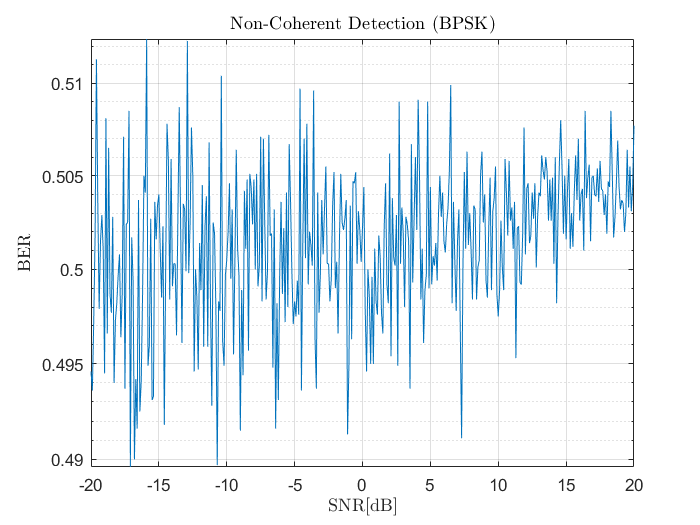

M = 2;
k = log2(M);
pkt_size = 1e4;
b_tx = bit_gen(pkt_size, k);
modulated_signal = 2 * b_tx - 1;
Eb = 1;
h = sqrt(0.5) * (randn(1, pkt_size) + 1i * randn(1, pkt_size));
SNR_db = -20:.1:20;
BER_NC = zeros(1,length(SNR_db));
for i = 1:length(SNR_db)
    snr_lin = db_to_lin(SNR_db(i));
    N0 = Eb./snr_lin;
    var_noise = (N0/2); 
    noise = randn(1, pkt_size) * sqrt(var_noise) + 1j .* randn(1, pkt_size) * sqrt(var_noise);
    y = h .* modulated_signal + noise;
    r = real(y);
    detected_bits = r;
    detected_bits(detected_bits>0) = 1;
    detected_bits(detected_bits<0) = 0;
    BER_NC(i) = length(find(detected_bits ~= b_tx))/numel(b_tx);
end
figure
semilogy(SNR_db, BER_NC)
title('Non-Coherent Detection (BPSK)',"Interpreter","latex")
xlabel('SNR[dB]',"Interpreter","latex")
ylabel('BER',"Interpreter","latex")
grid on

#### 
$$\left.b\right)\;\textrm{Detection}\;\textrm{without}\;\textrm{Fading}\;\textrm{Effect}$$


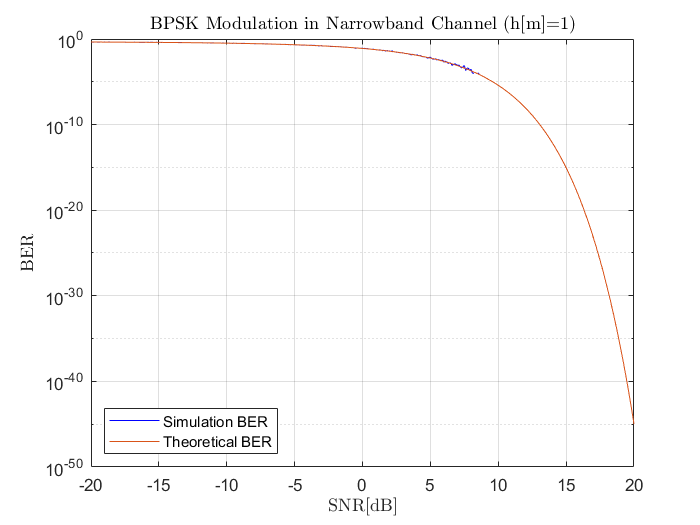

BER = zeros(1,length(SNR_db));
for i = 1:length(SNR_db)
    snr_lin = db_to_lin(SNR_db(i));
    N0 = Eb./snr_lin;
    var_noise = (N0/2); 
    noise = randn(1, pkt_size) * sqrt(var_noise) + 1j .* randn(1, pkt_size) * sqrt(var_noise);
    y = modulated_signal + noise;
    r = real(y);
    detected_bits = r;
    detected_bits(detected_bits>0) = 1;
    detected_bits(detected_bits<0) = 0;
    BER(i) = length(find(detected_bits ~= b_tx))/numel(b_tx);
end
figure
semilogy(SNR_db, BER,'b')
hold on 
berQ = berawgn(SNR_db,'psk',M,'nodiff');
semilogy(SNR_db, berQ)
legend('Simulation BER','Theoretical BER',"Location","southwest")
title('BPSK Modulation in Narrowband Channel (h[m]=1)',"Interpreter","latex")
xlabel('SNR[dB]',"Interpreter","latex")
ylabel('BER',"Interpreter","latex")
grid on

### 
$$\left.1-2\right)\;\textrm{Binary}\;\textrm{Pulse}-\textrm{Position}\;\textrm{Modulation}$$


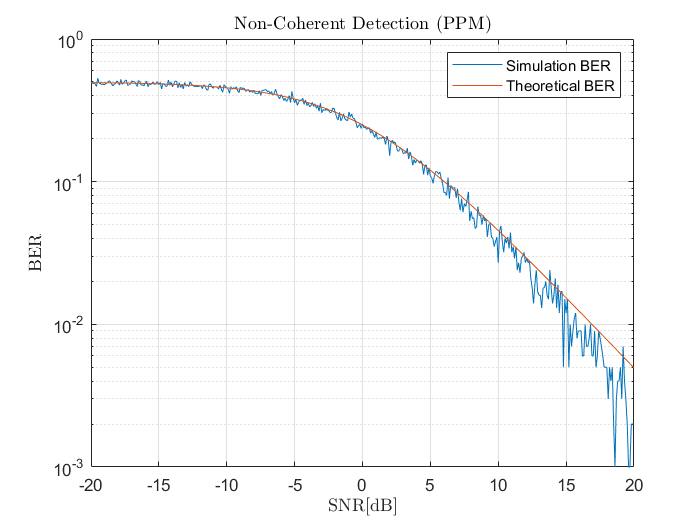

M = 2;
k = log2(M);
pkt_size = 1e3;
b_tx = bit_gen(pkt_size, k);
modulated_signal = ppm(b_tx);
Eb = 0.5;
h = sqrt(0.5) * (randn(pkt_size, 2) + 1i * randn(pkt_size, 2));
SNR_db = -20:.1:20;
BER_NC_PPM = zeros(1,length(SNR_db));
for i = 1:length(SNR_db)
    snr_lin = db_to_lin(SNR_db(i));
    N0 = Eb./snr_lin;
    var_noise = (N0/2); 
    noise = randn(pkt_size, 2) * sqrt(var_noise) + 1j .* randn(pkt_size, 2) * sqrt(var_noise);
    y = h .* modulated_signal + noise;
    detected_bits = zeros(1,pkt_size);
    detected_bits((abs(y(:,1))).^2>(abs(y(:,2))).^2) = 1;
    BER_NC_PPM(i) = length(find(detected_bits ~= b_tx))/numel(b_tx);
end
berP = 1./(2.*(1+db_to_lin(SNR_db)));
figure
semilogy(SNR_db, BER_NC_PPM, SNR_db, berP)
title('Non-Coherent Detection (PPM)',"Interpreter","latex")
legend('Simulation BER','Theoretical BER')
xlabel('SNR[dB]',"Interpreter","latex")
ylabel('BER',"Interpreter","latex")
grid on

### 
$$\left.1-3\right)\;\textrm{Coherent}\;\textrm{Detection}\;\textrm{in}\;\textrm{BPSK}\;\textrm{Modulation}$$
      

#### 
$$\left.a\right)\;\textrm{Theoretical}\;\textrm{and}\;\textrm{Simulation}\;\textrm{BER}$$


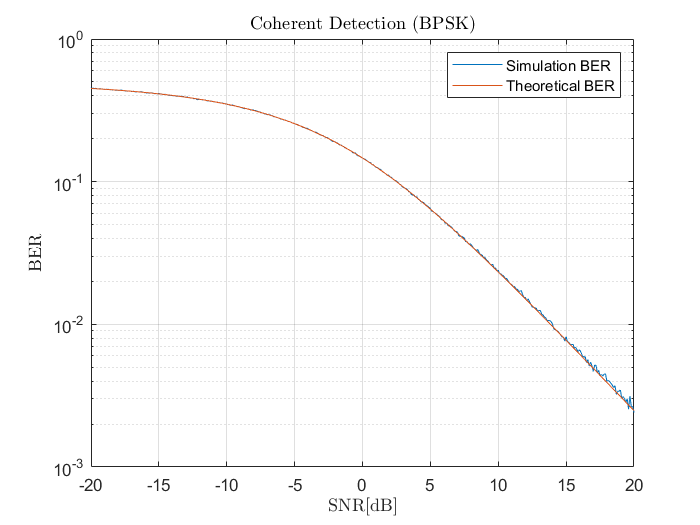

M = 2;
k = log2(M);
pkt_size = 1e5;
b_tx = bit_gen(pkt_size, k);
modulated_signal = 2 * b_tx - 1;
Eb = 1;
h = sqrt(0.5) * (randn(1, pkt_size) + 1i * randn(1, pkt_size));
SNR_db = -20:.1:20;
BER_C = zeros(1,length(SNR_db));
for i = 1:length(SNR_db)
    snr_lin = db_to_lin(SNR_db(i));
    N0 = Eb./snr_lin;
    var_noise = (N0/2); 
    noise = randn(1, pkt_size) * sqrt(var_noise) + 1j .* randn(1, pkt_size) * sqrt(var_noise);
    y = h .* modulated_signal + noise;
    r = real(y.*conj(h)./abs(h));
    detected_bits = r;
    detected_bits(detected_bits>0) = 1;
    detected_bits(detected_bits<0) = 0;
    BER_C(i) = length(find(detected_bits ~= b_tx))/numel(b_tx);
end
berB = 0.5 .* (1-sqrt(db_to_lin(SNR_db)./(1+db_to_lin(SNR_db))));
figure
semilogy(SNR_db, BER_C, SNR_db, berB)
title('Coherent Detection (BPSK)',"Interpreter","latex")
legend('Simulation BER','Theoretical BER')
xlabel('SNR[dB]',"Interpreter","latex")
ylabel('BER',"Interpreter","latex")
grid on

#### 
$$\left.b\right)\;\textrm{Coherent}\;\textrm{BPSK}\;\textrm{and}\;\textrm{Non}-\textrm{Coherent}\;\textrm{PPM}\;\textrm{Comparison}\;$$
 

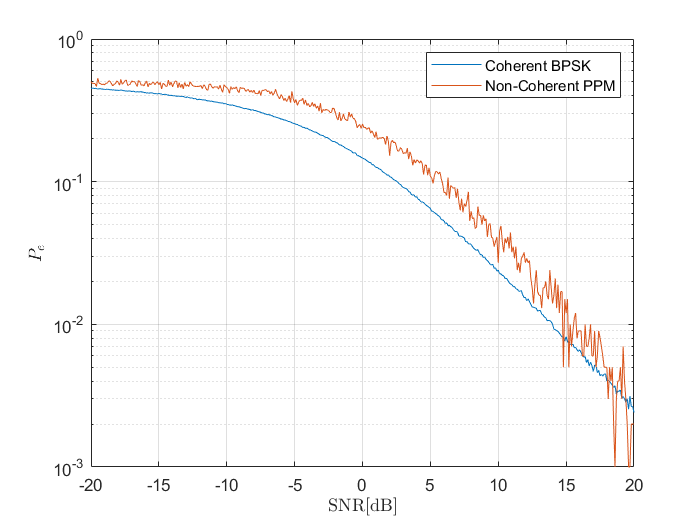

figure
semilogy(SNR_db, BER_C, SNR_db, BER_NC_PPM)
legend('Coherent BPSK','Non-Coherent PPM')
xlabel('SNR[dB]',"Interpreter","latex")
ylabel('$P_e$',"Interpreter","latex")
grid on

### 
$$\left.1-4\right)\;\textrm{Detection}\;\textrm{in}\;\textrm{ًQPSK}\;\textrm{Modulation}$$


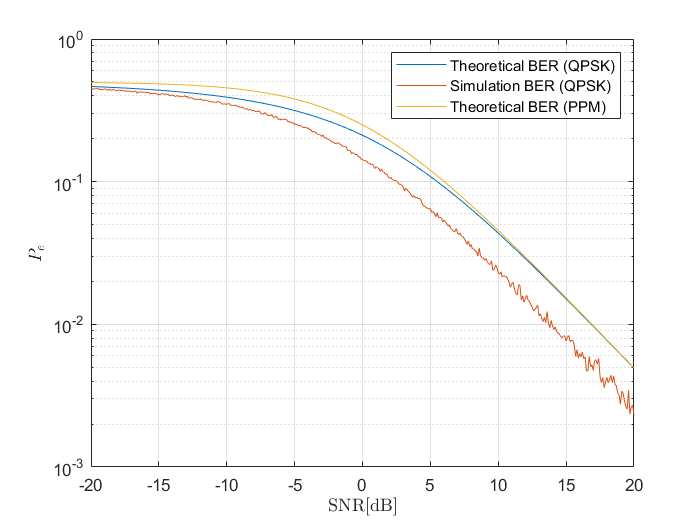

M = 4;
k = log2(M);
modulation = 'psk';
pkt_size = 1e4;
b_tx = bit_gen(pkt_size, k);
b_tx = transpose(b_tx);
b_gray = gray_code(k);
sym_idx = codding(b_tx,b_gray)-1;
[cons, Es_avg]  = constellation(M, modulation);
mod_sym = cons(sym_idx+1);
Eb = Es_avg/k;
h = sqrt(0.5) * (randn(pkt_size, 1) + 1i * randn(pkt_size, 1));
SNR_db = -20:.1:20;
BER_Q = zeros(1,length(SNR_db));
for i = 1:length(SNR_db)
    snr_lin = db_to_lin(SNR_db(i));
    N0 = Eb./snr_lin;
    var_noise = (N0/2); 
    noise = randn(pkt_size, 1) * sqrt(var_noise) + 1j .* randn(pkt_size, 1) * sqrt(var_noise);
    y = h .* mod_sym + noise;
    r = (y.*conj(h)./abs(h));
    [~,det_sym_idx] = min_dist_detector(r, cons);
    detected_bits = b_gray(det_sym_idx, :);
    BER_Q(i) = length(find(detected_bits ~= b_tx))/numel(b_tx);
end
berQ = 0.5 .* (1-sqrt(db_to_lin(SNR_db)./(2+db_to_lin(SNR_db))));
figure
semilogy(SNR_db, berQ, SNR_db, BER_Q, SNR_db, berP)
legend('Theoretical BER (QPSK)','Simulation BER (QPSK)','Theoretical BER (PPM)')
xlabel('SNR[dB]',"Interpreter","latex")
ylabel('$P_e$',"Interpreter","latex")
grid on

### 
$$\left.1-5\right)\;\textrm{Time}\;\textrm{Diversity}$$


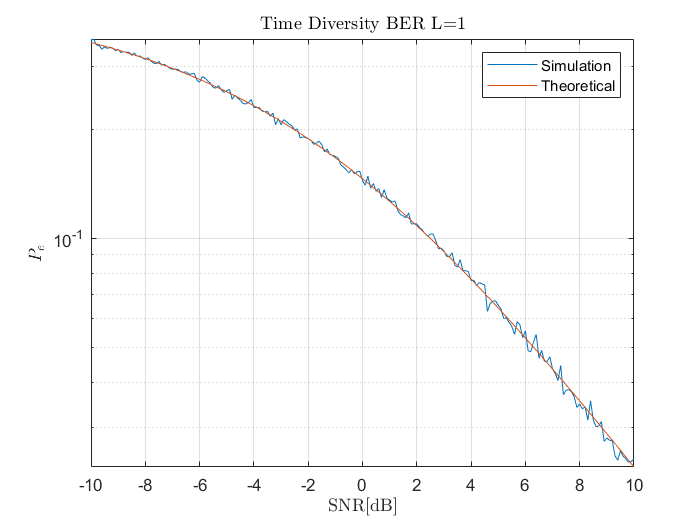

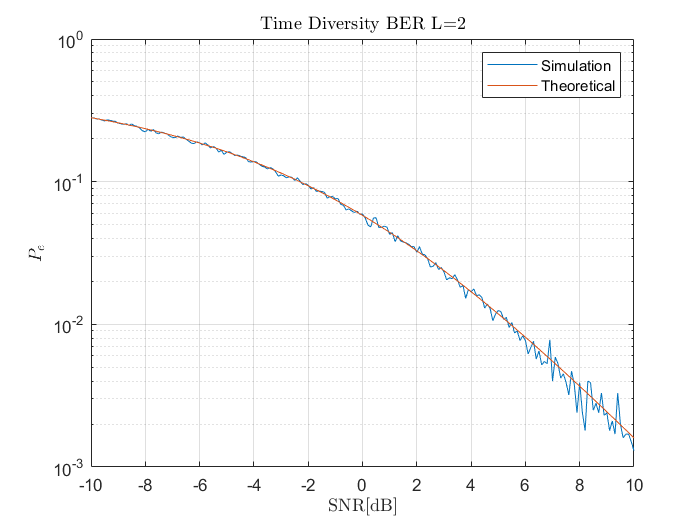

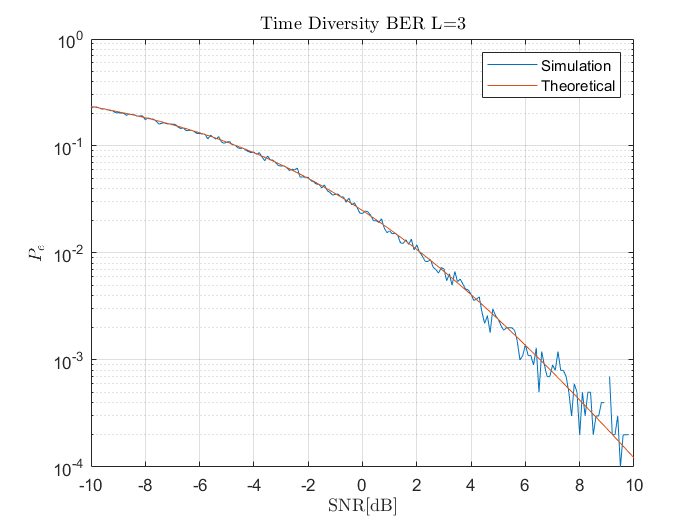

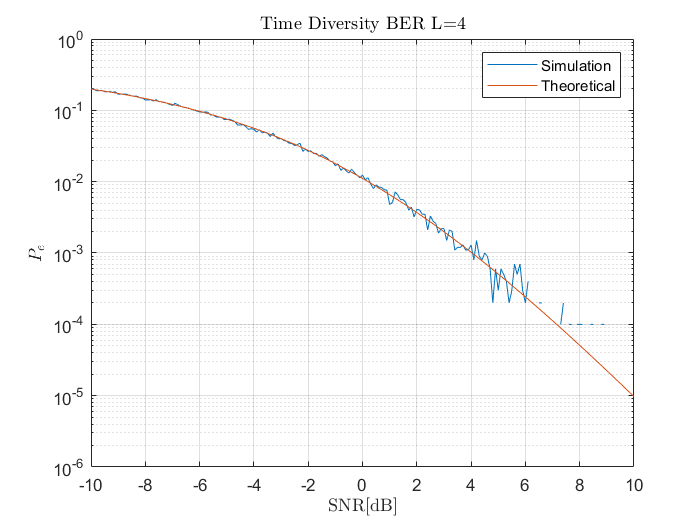

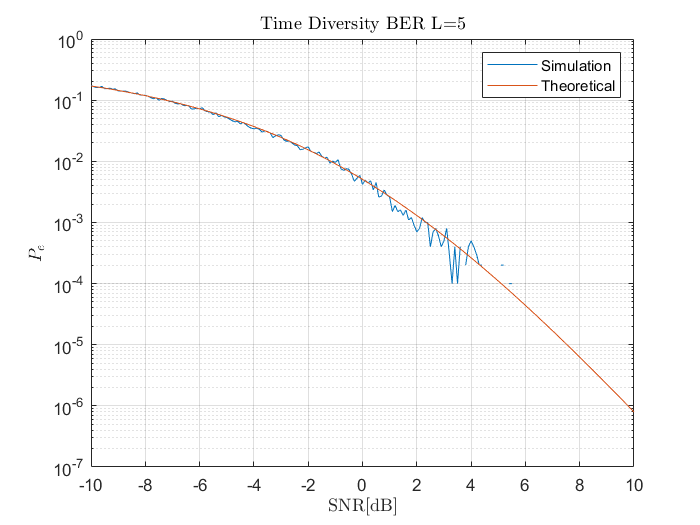

M = 2;
k = log2(M);
pkt_size = 1e4;
b_tx = bit_gen(pkt_size, k);
L = [1 2 3 4 5];
modulated_signal = 2 * b_tx' - 1;
Eb = 1;
SNR_db = -10:.1:10;
BER_TD = zeros(length(L),length(SNR_db));
BER_TD_theoretical = zeros(length(L),length(SNR_db));
tx = modulated_signal;
for l = 1:length(L)
    h = sqrt(0.5) * (randn(pkt_size, l) + 1i * randn(pkt_size, l));     
    for i = 1:length(SNR_db)
        temp = 0;
        snr_lin = db_to_lin(SNR_db(i));
        N0 = Eb./snr_lin;
        var_noise = (N0/2); 
        noise = randn(pkt_size, l) * sqrt(var_noise) + 1j .* randn(pkt_size, l) * sqrt(var_noise);
        y = h .* tx + noise;
        a = sqrt(((abs(h)).^2)/N0).*exp(-1i*angle(h)); 
        r = sum(y.*a,2); %Co-Phasing
        detected_bits = real(r);
        detected_bits(detected_bits>0) = 1;
        detected_bits(detected_bits<0) = 0;
        BER_TD(l,i) = length(find(detected_bits.' ~= b_tx))/numel(b_tx);
        mu = sqrt(snr_lin/(1+snr_lin));
        for j = 0:l-1   
            temp = temp + (nchoosek(l-1+j,j))*((1+mu)/2)^j;   
        end        
        BER_TD_theoretical(l,i) = (((1-mu)/2)^l)*temp;       
    end
    tx = [tx modulated_signal];
end

for l = 1 : length(L)
    figure
    semilogy(SNR_db, BER_TD(l,:), SNR_db, BER_TD_theoretical(l,:))
    title(['Time Diversity BER L=',num2str(l)],"Interpreter","latex")
    legend('Simulation','Theoretical');
    xlabel('SNR[dB]',"Interpreter","latex")
    ylabel('$P_e$',"Interpreter","latex")
    grid on
end

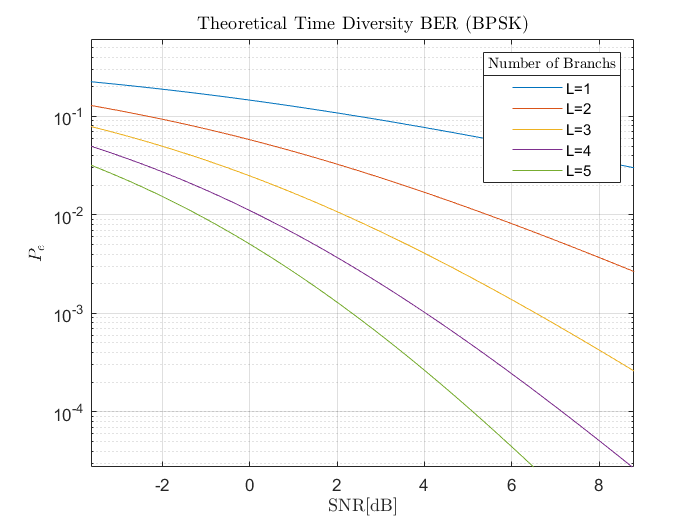

figure
semilogy(SNR_db, BER_TD_theoretical(1,:), SNR_db, BER_TD_theoretical(2,:), SNR_db, BER_TD_theoretical(3,:), SNR_db, BER_TD_theoretical(4,:), SNR_db, BER_TD_theoretical(5,:))
title('Theoretical Time Diversity BER (BPSK)',"Interpreter","latex")
leg2 = legend('L=1','L=2','L=3','L=4','L=5');
title(leg2,'Number of Branchs',"Interpreter","latex")
xlabel('SNR[dB]',"Interpreter","latex")
ylabel('$P_e$',"Interpreter","latex")
grid on

### 
$$\left.1-6\right)\;\textrm{Transmit}\;\textrm{Diversity}$$


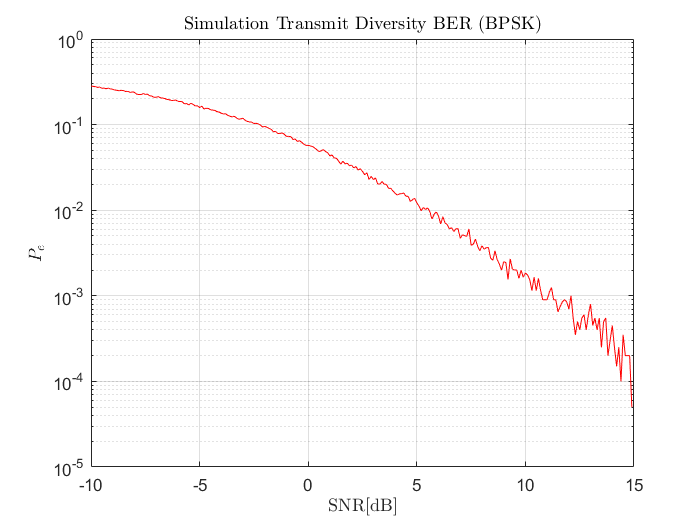

M = 2;
k = log2(M);
L = 2;
Eb = 1;
pkt_size = 1e4;
b_tx1 = bit_gen(pkt_size, k);
b_tx2 = bit_gen(pkt_size, k);
SNR_db = -10:0.1:15-0.1;
BER_SP = zeros(1,length(SNR_db));
for i = 1 : length(SNR_db)
    snr_lin = db_to_lin(SNR_db(i));
    N0 = Eb./snr_lin;
    var_noise = (N0/2);
    for j = 1 : pkt_size        
        h = sqrt(0.5) * (randn(L, 1) + 1j * randn(L, 1));
        n = sqrt(var_noise) * (randn(L,1) + 1j .* randn(L,1));
        s = zeros(2,1);
        s(1) = 2 * b_tx1(j) - 1;
        s(2) = 2 * b_tx2(j) - 1;
        Hc = [h(1) h(2) ; conj(h(2)) -conj(h(1))];
        y = Hc * s + n;
        z = Hc' * y;
        s_hat = zeros(length(z),1);
        for k = 1:length(z)
            if real(z(k))>0
                s_hat(k) =  1;
            else 
                s_hat(k) = -1;
            end
        end
        BER_SP(i) = BER_SP(i) + length(find(s_hat ~= s));
    end
    BER_SP(i) = BER_SP(i)/(2*pkt_size);
end
figure
semilogy(SNR_db, BER_SP, 'r')
title('Simulation Transmit Diversity BER (BPSK)',"Interpreter","latex")
xlabel('SNR[dB]',"Interpreter","latex")
ylabel('$P_e$',"Interpreter","latex")
grid on

## 
$$\left.\textrm{Part}\;2\right)\;\textrm{Frequency}\;\textrm{Selective}\;\textrm{Channel}$$


M = 2;
k = log2(M);
pkt_size = 2e6;
b_tx = bit_gen(pkt_size, k);
L = 200;
cp = L-1;
SNR_db = -10:40-1;
Nc = 8e4;
Block_Num = pkt_size/Nc;
a = 2 * b_tx - 1;

### 
$$\left.2-5\right)\;\textrm{Waterfilling}$$


iteration_num = 1e1;
BER_W = zeros(1,length(SNR_db));
detected_bits_W = zeros(1,pkt_size);
C = zeros(1,length(SNR_db));
for i = 1 : length(SNR_db)
    snr_lin = db_to_lin(SNR_db(i));
    Pmax = sum(a.^2);
    N0 = Pmax/(pkt_size * snr_lin);
    for j = 1 : Block_Num
        h = sqrt(0.5) * (randn(1,L) + randn(1,L)*1i);
        H = fft(h, Nc);
        a_block = a((j-1) * Nc + 1 : Nc * j);
        % Waterfilling
        ObjectiveFunction = @(lambda) Pmax - sum(max((1/lambda) - N0./(abs(H)).^2,0)); 
        % Initial guess for the root
        lambda0 = 1;     
        % Use fsolve to find the root
        root = fsolve(ObjectiveFunction, lambda0);
        P = max((1/root) - N0./(abs(H)).^2,0);
        C(i) = C(i) + sum(log2(1 + max(1/root - N0./abs(H).^2,0))); 
        a_block = a_block .* sqrt(P) .* exp(-1i .* angle(H));
        A_block = ifft(a_block,Nc);
        A_block_cp = [A_block(end-cp+1:end) , A_block];
        y = conv(A_block_cp, h);
        n = sqrt(N0/2) * (randn(1,Nc+cp) + 1j .* randn(1,Nc+cp));
        y = y(1:end-L+1) + n;
        y = y(cp+1:end);
        Y = fft(y,Nc);
        Z = real(Y);
        temp_W = Z;        
        temp_W(temp_W>0) = 1;
        temp_W(temp_W<0) = 0;
        detected_bits_W((j-1) * Nc + 1 : Nc * j) = temp_W;
    end
    C(i) = C(i) / Block_Num;
    BER_W(i) = length(find(detected_bits_W ~= b_tx))/numel(b_tx);
end


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>

Equation solved, solver stalled.

fsolve stopped because the relative 

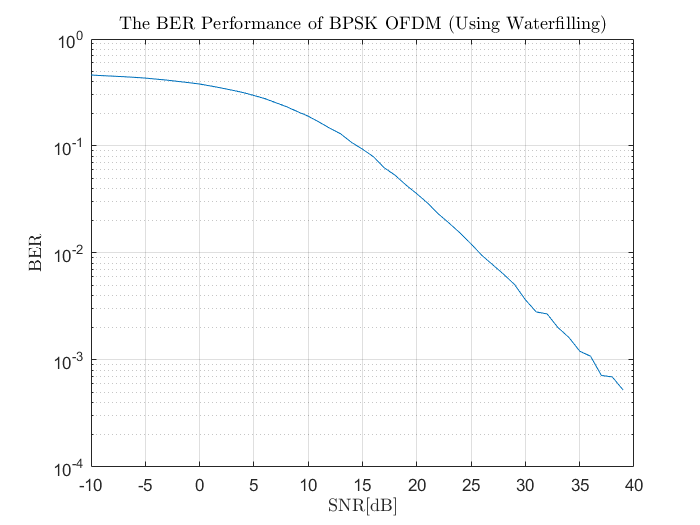

figure
semilogy(SNR_db, BER_W)
title('The BER Performance of BPSK OFDM (Using Waterfilling)',"Interpreter","latex")
xlabel('SNR[dB]',"Interpreter","latex")
ylabel('BER',"Interpreter","latex")
grid on

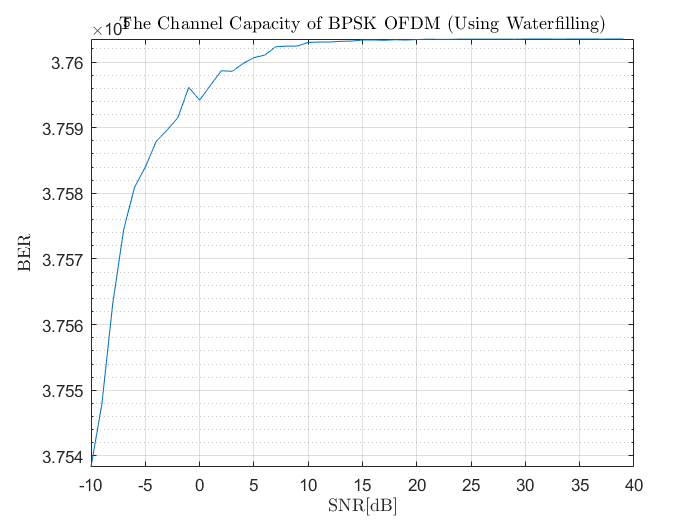

figure
semilogy(SNR_db, C)
title('The Channel Capacity of BPSK OFDM (Using Waterfilling)',"Interpreter","latex")
xlabel('SNR[dB]',"Interpreter","latex")
ylabel('BER',"Interpreter","latex")
grid on

### 
$$\left.2-6\right)\;\textrm{Receiver}\;\textrm{Diversity}$$


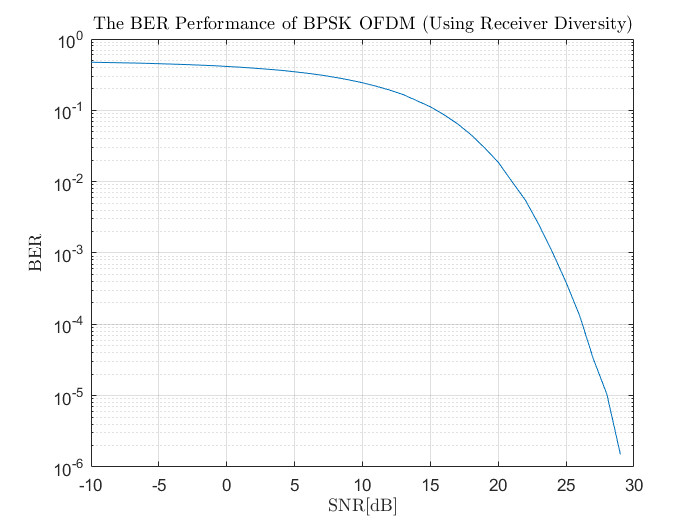

Receiver_Num = 10;
BER_RD = zeros(1,length(SNR_db));
detected_bits_RD = zeros(1,pkt_size);
for i = 1 : length(SNR_db)
    snr_lin = db_to_lin(SNR_db(i));
    Pmax = sum(a.^2);
    N0 = Pmax/(pkt_size * snr_lin);
    for j = 1 : Block_Num
        a_block = a((j-1) * Nc + 1 : Nc * j);
        A_block = ifft(a_block,Nc);
        A_block_cp = [A_block(end-cp+1:end) , A_block];
        h = zeros(Receiver_Num,L);
        H = zeros(Receiver_Num,Nc);
        n = zeros(Receiver_Num,cp+Nc);
        Y = zeros(Receiver_Num,Nc);
        R = zeros(Receiver_Num,Nc);
        for k = 1 : Receiver_Num
            h(k,:) = sqrt(0.5) * (randn(1,L) + randn(1,L)*1i);
            H(k,:) = fft(h(k,:), Nc);
            y = conv(A_block_cp, h(k,:));
            n(k,:) = sqrt(N0/2) * (randn(1,Nc+cp) + 1j .* randn(1,Nc+cp));
            y = y(1:end-L+1) + n(k,:);
            y = y(cp+1:end);
            Y(k,:) = fft(y,Nc);
            %Co-Phasing
            Co_phasing = sqrt(abs(H(k,:)).^2 ./ (Nc*N0)) .* exp(-1i * angle(H(k,:))) ;
            R(k,:) = Co_phasing .* Y(k,:);
        end      
        Z = sum(R,1);
        temp_RD = Z;        
        temp_RD(temp_RD>0) = 1;
        temp_RD(temp_RD<0) = 0;
        detected_bits_RD((j-1) * Nc + 1 : Nc * j) = temp_RD;
    end
    BER_RD(i) = length(find(detected_bits_RD ~= b_tx))/numel(b_tx);
end
figure
semilogy(SNR_db, BER_RD)
title('The BER Performance of BPSK OFDM (Using Receiver Diversity)',"Interpreter","latex")
xlabel('SNR[dB]',"Interpreter","latex")
ylabel('BER',"Interpreter","latex")
grid on

### 
$$\left.2-7\right)\;\textrm{ZF}\;\&\;\textrm{MMSE}$$


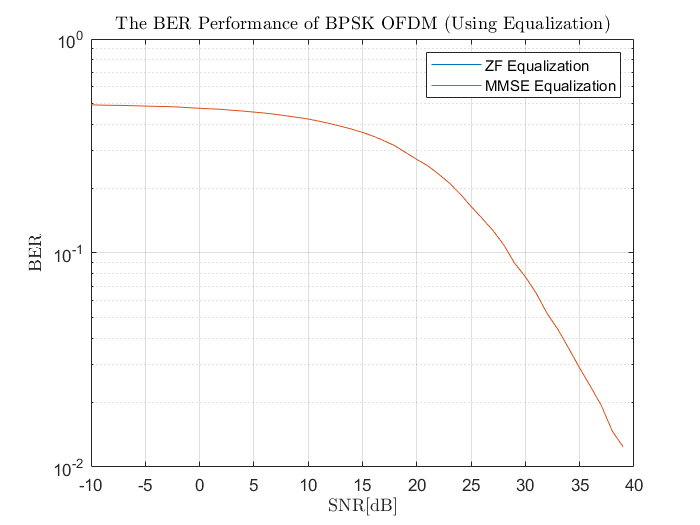

BER_ZF = zeros(1,length(SNR_db));
BER_MMSE = zeros(1,length(SNR_db));
detected_bits_ZF = zeros(1,pkt_size);
detected_bits_MMSE = zeros(1,pkt_size);
for i = 1 : length(SNR_db)
    snr_lin = db_to_lin(SNR_db(i));
    Pmax = sum(a.^2);
    N0 = Pmax/(pkt_size * snr_lin);
    for j = 1 : Block_Num
        a_block = a((j-1) * Nc + 1 : Nc * j);
        A_block = ifft(a_block,Nc);
        A_block_cp = [A_block(end-cp+1:end) , A_block];
        h = sqrt(0.5) * (randn(1,L) + randn(1,L)*1i);
        H = fft(h, Nc);
        y = conv(A_block_cp, h);
        n = sqrt(N0/2) * (randn(1,Nc+cp) + 1j .* randn(1,Nc+cp));
        y = y(1:end-L+1) + n;
        y = y(cp+1:end);
        Y = fft(y,Nc);
        %Eqz
        W_ZF = 1 ./ H;
        W_MMSE = conj(H) ./ ((abs(H)).^2 + N0);
        Z1 = real(Y .* W_ZF);
        Z2 = real(Y .* W_MMSE);
        temp_ZF = Z1;        
        temp_ZF(temp_ZF>0) = 1;
        temp_ZF(temp_ZF<0) = 0;
        detected_bits_ZF((j-1) * Nc + 1 : Nc * j) = temp_ZF;
        temp_MMSE = Z2;        
        temp_MMSE(temp_MMSE>0) = 1;
        temp_MMSE(temp_MMSE<0) = 0;
        detected_bits_MMSE((j-1) * Nc + 1 : Nc * j) = temp_MMSE;
    end
    BER_ZF(i) = length(find(detected_bits_ZF ~= b_tx))/numel(b_tx);
    BER_MMSE(i) = length(find(detected_bits_MMSE ~= b_tx))/numel(b_tx);
end
figure
semilogy(SNR_db, BER_ZF, SNR_db, BER_MMSE)
title('The BER Performance of BPSK OFDM (Using Equalization)',"Interpreter","latex")
legend('ZF Equalization','MMSE Equalization')
xlabel('SNR[dB]',"Interpreter","latex")
ylabel('BER',"Interpreter","latex")
grid on

### 
$$\left.2-8\right)\;\textrm{Clipping}$$


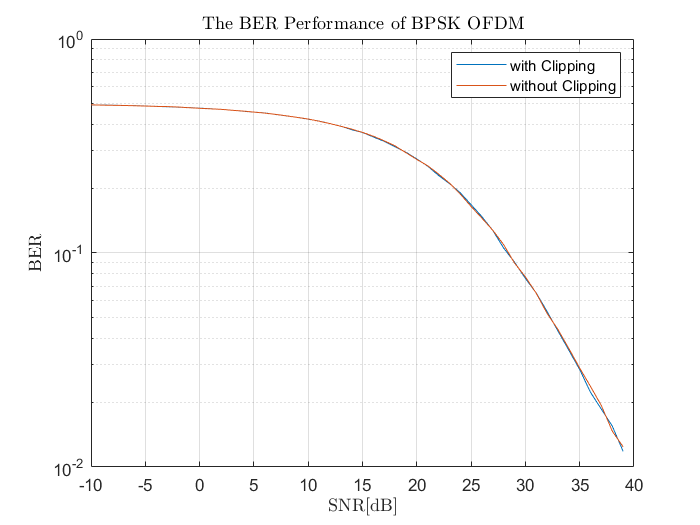

BER_Clipping = zeros(1,length(SNR_db));
detected_bits_Clipping = zeros(1,pkt_size);
for i = 1 : length(SNR_db)
    snr_lin = db_to_lin(SNR_db(i));
    Pmax = sum(a.^2);
    N0 = Pmax/(pkt_size * snr_lin);
    for j = 1 : Block_Num
        a_block = a((j-1) * Nc + 1 : Nc * j);
        A_block = ifft(a_block,Nc);
        idx = abs(A_block) >= 0.8 * max(abs(A_block));
        A_block(idx) = (A_block(idx)) .* 0.8 * max(abs(A_block)) ./ abs(A_block(idx));
        A_block_cp = [A_block(end-cp+1:end) , A_block];
        h = sqrt(0.5) * (randn(1,L) + randn(1,L)*1i);
        H = fft(h, Nc);
        y = conv(A_block_cp, h);
        n = sqrt(N0/2) * (randn(1,Nc+cp) + 1j .* randn(1,Nc+cp));
        y = y(1:end-L+1) + n;
        y = y(cp+1:end);
        Y = fft(y,Nc);
        %Eqz
        W_MMSE = conj(H) ./ ((abs(H)).^2 + N0);
        Z = real(Y .* W_MMSE);
        temp_Clipping = Z;        
        temp_Clipping(temp_Clipping>0) = 1;
        temp_Clipping(temp_Clipping<0) = 0;
        detected_bits_Clipping((j-1) * Nc + 1 : Nc * j) = temp_Clipping;
    end
    BER_Clipping(i) = length(find(detected_bits_Clipping ~= b_tx))/numel(b_tx);
end
figure
semilogy(SNR_db, BER_Clipping, SNR_db, BER_MMSE)
title('The BER Performance of BPSK OFDM',"Interpreter","latex")
legend('with Clipping','without Clipping')
xlabel('SNR[dB]',"Interpreter","latex")
ylabel('BER',"Interpreter","latex")
grid on

# **Required Functions:**

## 
$$\textrm{Random}\;\textrm{Bit}\;\textrm{Generator}:$$


function res = bit_gen(pkt_size, k)
    res = randi([0 1], k, pkt_size);
end

## 
$$\textrm{dB}\;\textrm{to}\;\textrm{linear}\;\textrm{Function}:$$


function out = db_to_lin(in)
    out = 10.^(in/10);
end

## 
$$\textrm{Binary}\;\textrm{Pulse}\;\textrm{Postion}\;\textrm{Modulation}:$$


function ppm_mod = ppm(b_tx)
    ppm_mod = zeros(length(b_tx),2);
    for i = 1:length(b_tx)
        if b_tx(i) == 0  
            ppm_mod(i,2) = 1;
        else
            ppm_mod(i,1) = 1;
        end
    end
end

## 
$$\textrm{Gray}\;\textrm{Code}\;\textrm{Generator}:$$


function [b_gray] = gray_code(k)
    A = [0;1];
    if k==1
        b_gray = A;
    else
      for i=2:k
        z = zeros(2^(i-1),1); 
        o = ones(2^(i-1),1);
        B = circshift(A, 1);
        A = [z A ; o B];            
      end                  
    end
    b_gray = A;
end

## 
$$\textrm{Encodding}:$$


function [sym_idx] = codding(b_tx,b_gray)
    sym_idx = zeros(length(b_tx),1);
    for i=1:length(b_tx)
        for j=1:length(b_gray)
            if b_tx(i,:) == b_gray(j,:)
                sym_idx(i,:) = j;
            end
        end        
    end
end

## 
$$\textrm{Constellation}:$$


function [cons, Es_avg] = constellation(M, modulation)
    if strcmpi(modulation, 'psk')
        cons = ((0:M-1)*2*pi/M)';
        cons = exp(1j*(cons+pi/4));
        cons = cons/sqrt(abs(cons'*cons)/M);
        Es_avg = abs(cons'*cons)/M;
    end
end

## 
$$\textrm{Minimum}\;\textrm{Distance}\;\textrm{Detector}:$$


function [det_sym,det_sym_idx] = min_dist_detector(rx_sym, constellation)
    r = length(rx_sym);
    det_sym = zeros(1, r);
    det_sym_idx = zeros(1, r);
    for i = 1:r
        [~, index] = min(abs(constellation - rx_sym(i)));
        det_sym_idx(i) = index ;
        det_sym(i) = constellation(index);
    end
end